# Homework 10

## [✔] ADSI Problem 6.2: Autocorrelation expression for an AR(1) process (proof)

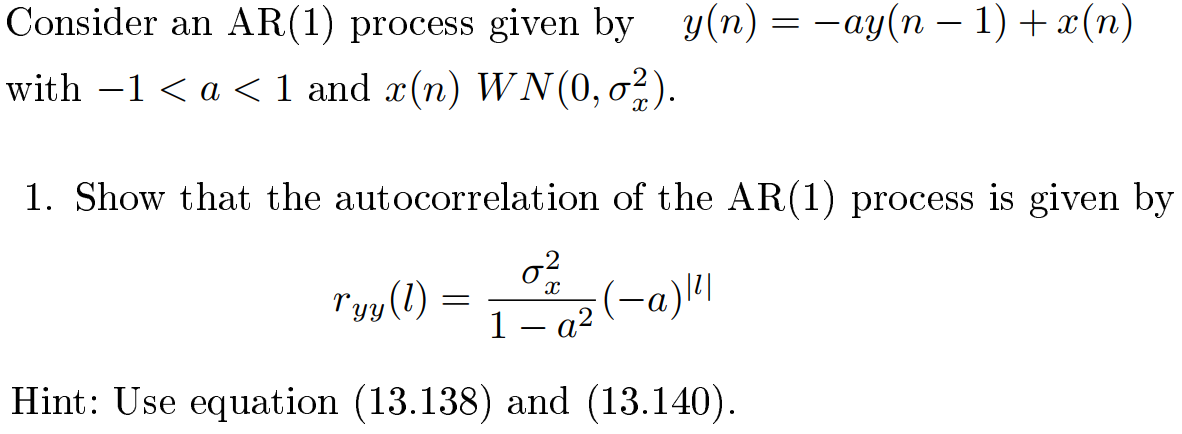

The autocorrelation of an AR(p) process is given by Eq. 13.138:

        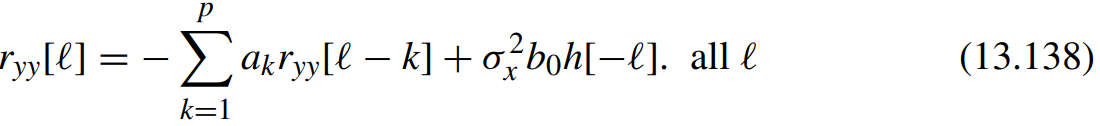

where $h\left\lbrack n\right\rbrack$ is the impulse response of an all-pole system.

Equation 13.138 is an general expression for all $\ell$. However, since $h\left\lbrack \ell \right\rbrack =0$ for negative values of $\ell$ then we know that $h\left\lbrack -\ell \right\rbrack =0$. Therefore, Eq. 13.138 can be reduced to:

        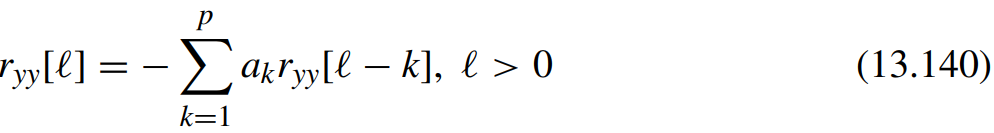

For an AR(1) process, Eq. 13.138 simplifies to:

        $r_{\mathrm{yy}} \left\lbrack \ell \right\rbrack =-a_1 r_{\mathrm{yy}} \left\lbrack \ell -1\right\rbrack +\sigma_x^2 b_0 h\left\lbrack -\ell \right\rbrack$ for all $\ell$

For an AR(1) process, Eq. 13.140 simplifies to:

        $r_{\mathrm{yy}} \left\lbrack \ell \right\rbrack =-a_1 r_{\mathrm{yy}} \left\lbrack \ell -1\right\rbrack$ for $\ell >0$

Setting $\ell =0$ in the first equation, we get:

        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack -1\right\rbrack +\sigma_x^2 b_0 h\left\lbrack 0\right\rbrack$$


The book says that $h\left\lbrack 0\right\rbrack =b_0 =1$ so we are left with:

        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack -1\right\rbrack +\sigma_x^2$$


We can use the symmetry property of autocorrelation function i.e., $r_{\mathrm{yy}} \left\lbrack -\ell \right\rbrack =r_{\mathrm{yy}} \left\lbrack -\ell \right\rbrack$:

        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 1\right\rbrack +\sigma_x^2$$


To find an expression for $r_{\mathrm{yy}} \left\lbrack 1\right\rbrack$, we set $\ell =1$ in the second equation:

        
$$r_{\textrm{yy}} \left\lbrack 1\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 0\right\rbrack$$


We insert the second equation into the first equation:

        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =-a_1 \left(-a_1 r_{\textrm{yy}} \left\lbrack 0\right\rbrack \right)+\sigma_x^2$$


        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =a_1^2 r_{\mathrm{yy}} \left\lbrack 0\right\rbrack +\sigma_x^2$$


        
$$\sigma_x^2 =r_{\textrm{yy}} \left\lbrack 0\right\rbrack -a_1^2 r_{\textrm{yy}} \left\lbrack 0\right\rbrack$$


        
$$\sigma_x^2 =r_{\textrm{yy}} \left\lbrack 0\right\rbrack \left(1-a_1^2 \right)$$


        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =\frac{\sigma_x^2 }{1-a_1^2 }$$


Now, we need to find an expression for $\ell >0$. We can do this by using the second equation.

First, we set $\ell =1$ in the second equation:

        
$$r_{\textrm{yy}} \left\lbrack 1\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 0\right\rbrack \Leftrightarrow -a_1 \frac{\sigma_x^2 }{1-a_1^2 }$$


        
$$r_{\textrm{yy}} \left\lbrack 2\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 1\right\rbrack \Leftrightarrow -a_1 \left(-a_1 \frac{\sigma_x^2 }{1-a_1^2 }\right)\Leftrightarrow {\left(-a_1 \right)}^2 \frac{\sigma_x^2 }{1-a_1^2 }$$


        
$$r_{\textrm{yy}} \left\lbrack 3\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 2\right\rbrack \Leftrightarrow -a_1 \left({\left(-a_1 \right)}^2 \frac{\sigma_x^2 }{1-a_1^2 }\right)\Leftrightarrow {\left(-a_1 \right)}^3 \frac{\sigma_x^2 }{1-a_1^2 }$$


This means that in general, we have:

        
$$r_{\textrm{yy}} \left\lbrack \ell \right\rbrack ={\left(-a_1 \right)}^{\ell } \frac{\sigma_x^2 }{1-a_1^2 }$$


If we apply the symmetric property of the autocorrelation, we get:

        
$$r_{\textrm{yy}} \left\lbrack \ell \right\rbrack ={\left(-a_1 \right)}^{\left|\ell \right|} \frac{\sigma_x^2 }{1-a_1^2 }$$


## ADSI Problem 6.3: Wiener FIR Filtering, minimum square error

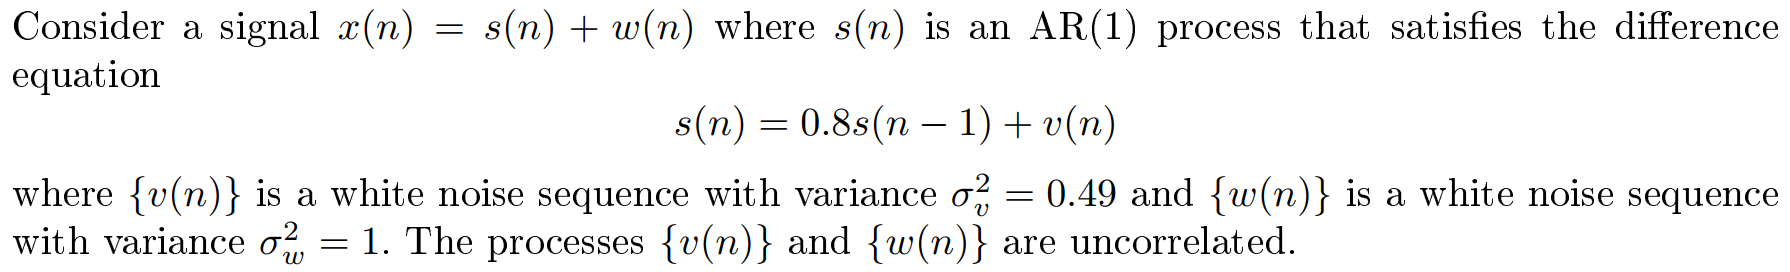

        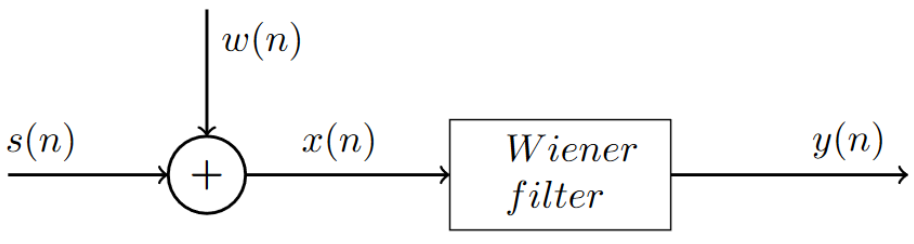

clear variables;

### [✔] 1) Determine the autocorrelation sequence for a signal with two noise processes

In Problem 6.2, we found that the autocorrelation function of an AR(1) is:

        
$$r_{\mathrm{yy}}^{\mathrm{AR}\left(1\right)} \left(\ell \right)={\left(-a_1 \right)}^{\left|\ell \right|} \frac{\sigma_x^2 }{1-a_1^2 }$$


For the AR(1) process, we are given $a_1 =-0\ldotp 8$ and $\sigma_v^2 =0\ldotp 49$. So the autocorrelation sequence for $s\left(n\right)$ is:

        
$$r_{\mathrm{ss}} \left(\ell \right)={0\ldotp 8}^{\left|\ell \right|} \frac{0\ldotp 49}{1-{\left(-0\ldotp 8\right)}^2 }={0\ldotp 8}^{\left|\ell \right|} \frac{0\ldotp 49}{0\ldotp 36}$$


Next, we need to find the autucorrelation sequence for $w\left(n\right)$. The autocorrelation of white Gaussian noise is $\sigma_w^2 \delta \left(\ell \right)$ so since white noise has unit variance i.e. $\sigma_w^2 =1$ we have:

        
$$r_{\mathrm{ww}} \left(\ell \right)=\delta \left(\ell \right)$$


Since the two noise processes are uncorrelated, the ACRS of $\left\lbrace x\left(n\right)\right\rbrace$ process is:

        
$$r_{\mathrm{xx}} \left(\ell \right)={0\ldotp 8}^{\left|\ell \right|} \frac{0\ldotp 49}{0\ldotp 36}+\delta \left(\ell \right)$$


### [👀] 2) Design a Wiener filter of length M=2 to estimate an AR(1) process

The optimum Wiener filter to estimate a random process is given by Eq. 14.109:

        

where ${\mathit{\mathbf{R}}}_x$ is the correlation matrix of a random vector $\mathit{\mathbf{x}}$ and $\mathit{\mathbf{g}}$ is the cross-correlation vector between $\mathit{\mathbf{x}}$ and $y$ (the signal that we want to recover which in this problem is $s\left\lbrack n\right\rbrack$). 

Basically, to design a $p$th order Wiener filter, we have to solve following equation with respect to $\mathit{\mathbf{h}}$:

        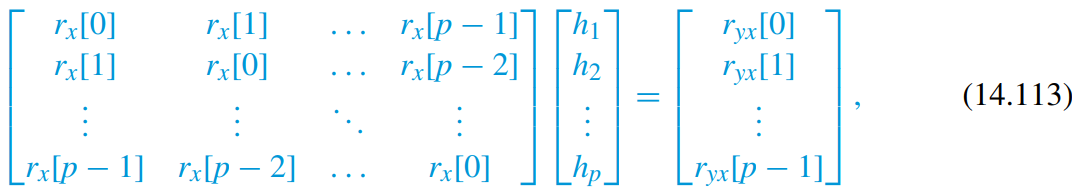

Computing the autocorrelation matrix is straightforward since we have computed the autocorrelation $r_{\textrm{xx}} \left(\ell \right)$ in part 1).

M = 2;
ell = 0:M-1;

r_ss = 0.8.^abs(ell) * (0.49/0.36);
r_ww = (ell == 0); % Simulate the delta function
r_xx = r_ss + r_ww;
R_xx = toeplitz(r_xx)

R_xx =     2.3611    1.0889
    1.0889    2.3611


We have to come up with an expression for the cross-correlation $r_{\textrm{sx}} \left(\ell \right)$:

        
$$r_{\mathrm{sx}} \left(\ell \right)=E\left\lbrack s\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{sx}} \left(\ell \right)=E\left\lbrack s\left(n\right)\left(s\left(n-\ell \right)+w\left(n-\ell \right)\right)\right\rbrack$$


        
$$r_{\textrm{sx}} \left(\ell \right)=E\left\lbrack s\left(n\right)s\left(n-\ell \right)+s\left(n\right)w\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{sx}} \left(\ell \right)=E\left\lbrack s\left(n\right)s\left(n-\ell \right)\right\rbrack +E\left\lbrack s\left(n\right)w\left(n-\ell \right)\right\rbrack$$


Since the processes $s\left(n\right)$ and $w\left(n\right)$ are uncorrelated:

        
$$r_{\textrm{sx}} \left(\ell \right)=E\left\lbrack s\left(n\right)s\left(n-\ell \right)\right\rbrack +E\left\lbrack s\left(n\right)\right\rbrack \cdot E\left\lbrack w\left(n-\ell \right)\right\rbrack$$


👀 ***Is it okay to make this assumption?***

We assume that $w\left(n\right)$ is a zero-mean WGN, we know that $E\left\lbrack w\left(n\right)\right\rbrack =0$, so we are left with

        
$$r_{\textrm{sx}} \left(\ell \right)=r_{\mathrm{ss}} \left(\ell \right)+0$$


From 1), we know the that:

        
$$r_{\textrm{ss}} \left(\ell \right)={0\ldotp 8}^{\left|\ell \right|} \frac{0\ldotp 49}{0\ldotp 36}$$


g = r_ss';

h_opt = R_xx\g % Same as `inv(R_xx)*g` but better

h_opt =     0.4621
    0.2481


### [✔] 3) Determine the minimum mean square error for M=2

The minimum square error for an optimum $p$th Wiener (FIR) filter is given by Eq. 14.115:

        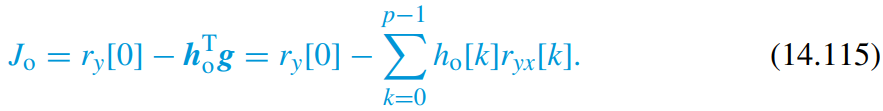

mse = r_ss(1) - h_opt'*g

mse = 0.4621

## ADSI Problem 6.4: Linear interpolation, estimate missing samples

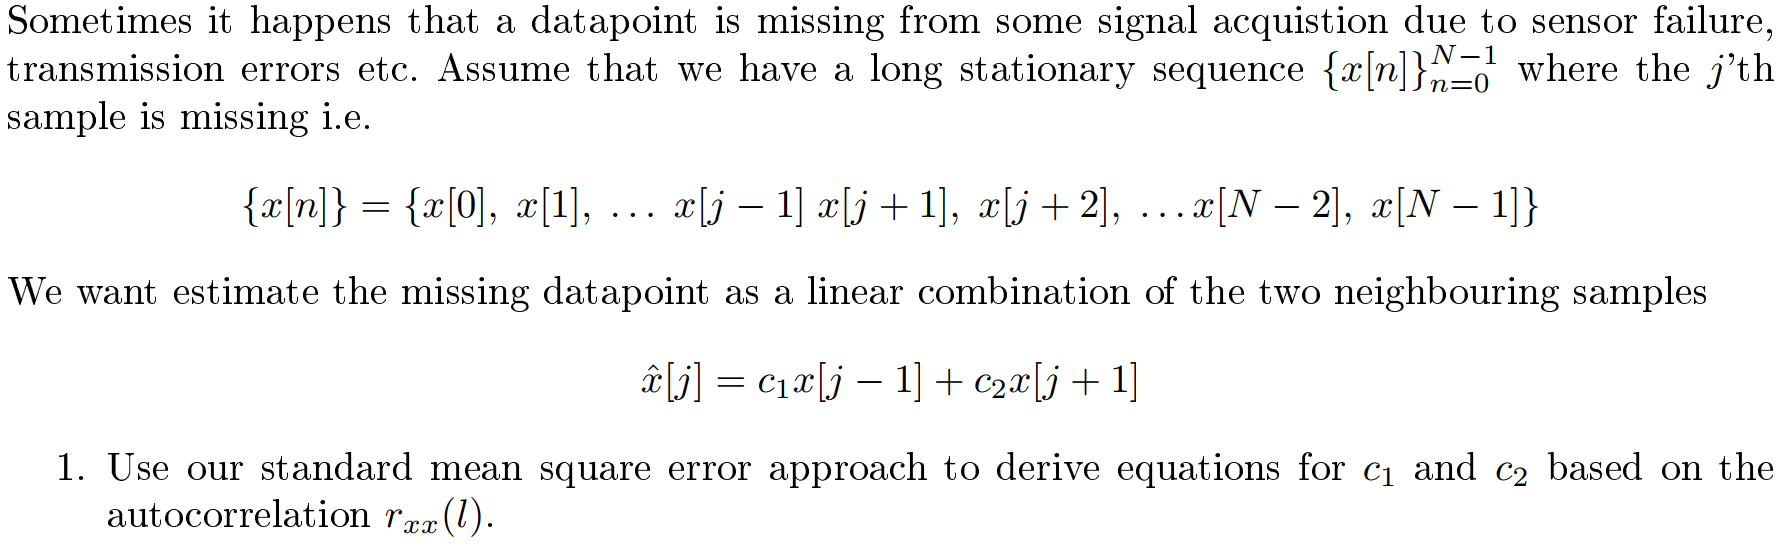

### 1) Use mean square error to derive coefficients based on the ACRS

## ADSI Problem 6.5: Levinson-Durbin by Hand

*The aim of this problem is to get a finger-tip feeling of the flow of the Levinson-Durbin recursion. Assume that the following autocorrelation function values have been determined from an unknown random process  *$\left\lbrace x\left(n\right)\right\rbrace$

        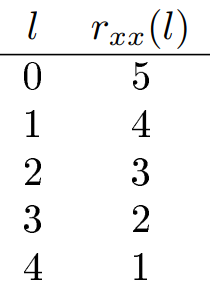

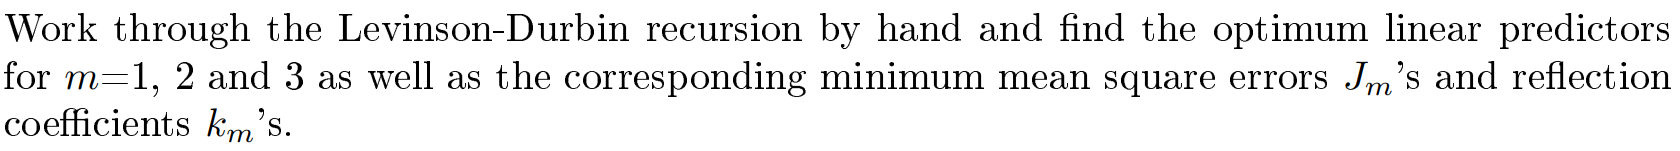

### 1) Work though Levinson-Durbin by hand to find the optimum linear predictors for m=1,2,3

### 2) Find the corresponding minimum mean square errors

### 3) Find the corresponding reflection coefficients

## ADSI Problem 6.6: Levinson-Durbin and linear prediction

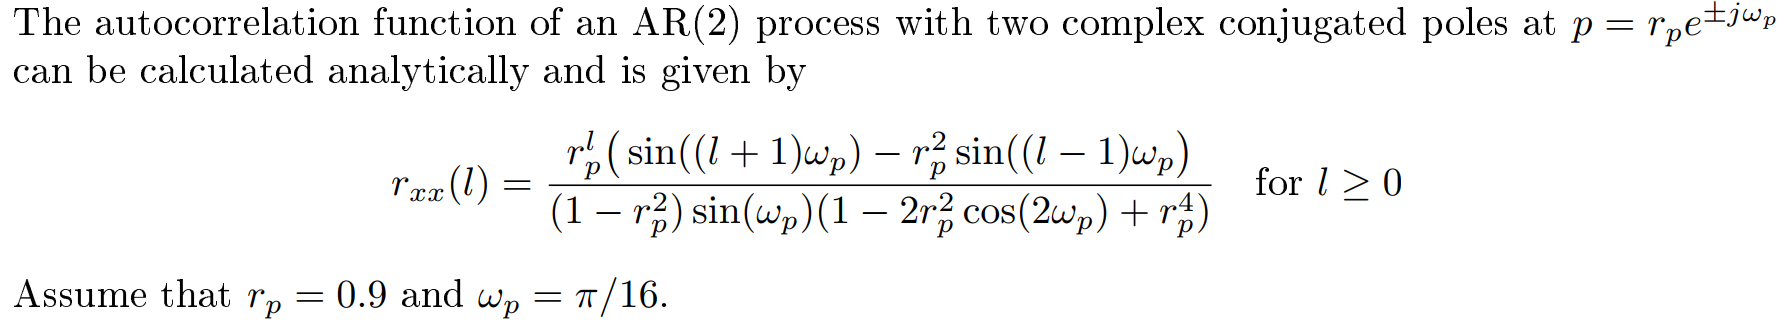

### 1) Plot the autocorrelation function.

### 2) Compute reflection coefficients for m'th order optimum linear predictors

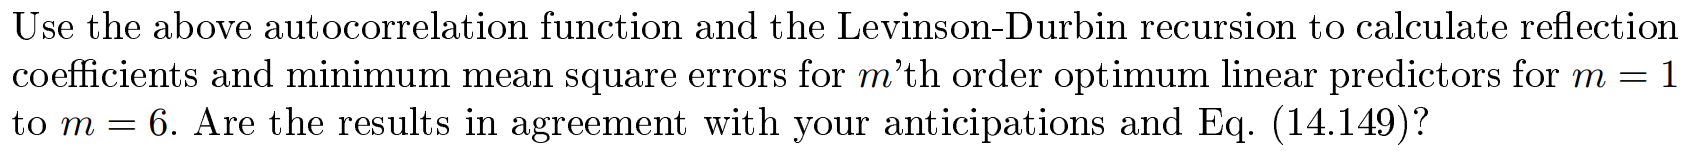

## ADSI Problem 6.7: Linear prediction

This problem addresses linear prediction on a simple harmonic signal where the results can be compared with our intuitive understanding.  

        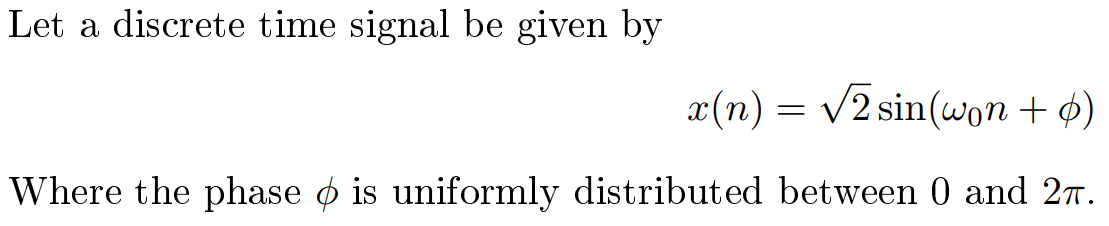

### 1) Determine the autocorrelation function for *x*(*n*)

### 2) Determine the 2nd order forward linear prediction filter

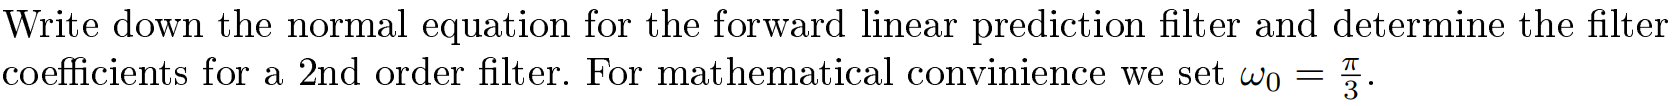

### 3) Find the system function for the filter and locate the zeros

### 4) Determine the frequency response, plot it and comment on the result

### 5) Calculate the prediction error

## ADSI Problem 6.8: Autocorrelation function and linear prediction

*Assume that for a given sequence of data *$\left\lbrace x\left(n\right)\right\rbrace$* the autocorrelation function has been calculated and used to solve the normal equations so that the optimum p'th order linear predictor was found. Now, an amplifier is placed in the signal chain so that the signal is *$\left\lbrace c\cdot x\left(n\right)\right\rbrace$*. How does the autocorrelation function and the linear predictor change?*

# Functions